**System 2**

a=19;
b=8;
c=a+b;

**Lead Compensator**

G2=tf([a*c*(-0.002) a*c],[7 3*(b/15) (c^2)])

G2 =
 
    -1.026 s + 513
  -------------------
  7 s^2 + 1.6 s + 729
 
Continuous-time transfer function.



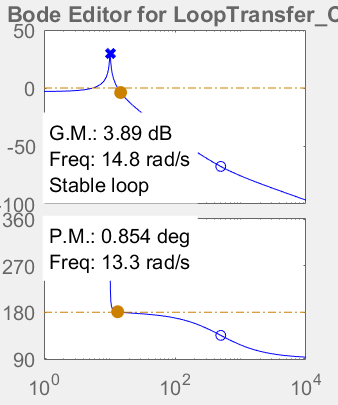

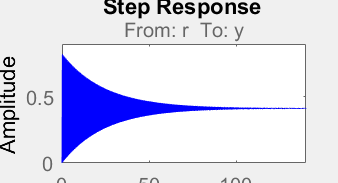

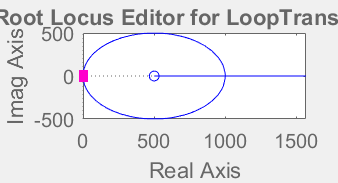

%sisotool(G2)

Ess2=10/100;
kG2=a/c

kG2 = 0.7037

kC2=(1-Ess2)/(Ess2*kG2)

kC2 = 12.7895

xG2=-60;
yG2=-120;
zG2=(yG2*kC2)/xG2

zG2 = 25.5789

C2=zpk([xG2],[yG2],[zG2])

C2 =
 
  25.579 (s+60)
  -------------
     (s+120)
 
Continuous-time zero/pole/gain model.



**Lead-Lag Compensator**

EssL2=5/100;
%Lead
kG2_LC=a/c

kG2_LC = 0.7037

kC2_LC=xG2*zG2/yG2

kC2_LC = 12.7895

C2_LC=zpk([xG2],[yG2],[zG2])

C2_LC =
 
  25.579 (s+60)
  -------------
     (s+120)
 
Continuous-time zero/pole/gain model.




%Lag
kC2_LgC=(1-EssL2)/(EssL2*kG2_LC*kC2_LC)

kC2_LgC = 2.1111

xlg2=-4;
ylg2=xlg2/kC2_LgC

ylg2 = -1.8947

C2_LgC=zpk([xlg2],[ylg2],[1])

C2_LgC =
 
    (s+4)
  ---------
  (s+1.895)
 
Continuous-time zero/pole/gain model.



C2_C=C2_LC*C2_LgC

C2_C =
 
  25.579 (s+60) (s+4)
  -------------------
   (s+120) (s+1.895)
 
Continuous-time zero/pole/gain model.

